# Actividad 1 - Modelo de Malthus y modelo logístico

### 1.1 - Comparación de los modelos

En un parque natural se desea introducir una especie animal emblemática con un programa de protección y repoblación. Vamos a suponer que la citada población en el tiempo t, medido en años, venga dada por la función y = y(t), medida en unidades de individuos.

%% MODELO DE MALTHUS
% Definición de la función simbólica y(t)
syms y(t)

% Definición de la primera derivada 
Dy = diff(y);

% EDO de primer orden
eqn = Dy ==  4 / 7 * y;

% Condiciones iniciales en froma de vector
cond = y(0) == 1000;

% Solución particular de la EDO del modelo de Malthus
y1 = dsolve(eqn, cond)

$$y1 = 1000\,{\mathrm{e}}^{\frac{4\,t}{7}}$$


t = 20;
individuos_1 = eval(y1)

individuos_1 = 9.1911e+07

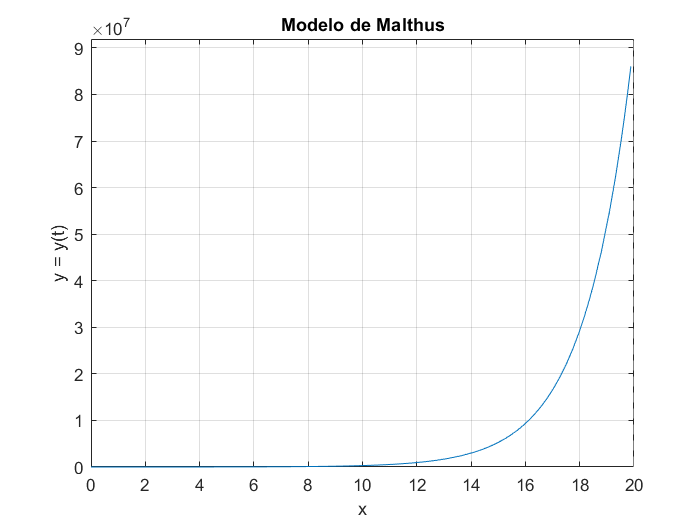


% Representación de la función y para t en [0, 20]. 
fplot(y1, [0, 20]), grid
xlabel('x'), ylabel('y = y(t)')
title('Modelo de Malthus')


%% MODELO LOGÍSTICO
eqn2 = Dy == 4 / 7 * y - (y^2 / 7000);

% Solución particular de la EDO del modelo logístico
y2 = dsolve(eqn2, cond)

$$y2 = \frac{4000}{{\mathrm{e}}^{\log\left(3\right)-\frac{4\,t}{7}}+1}$$

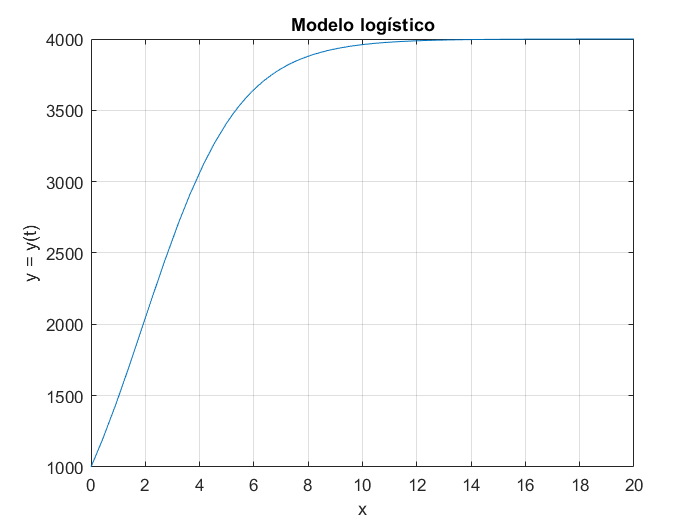


% Representación de la función y para t en [0, 20]. 
fplot(y2, [0, 20]), grid
xlabel('x'), ylabel('y = y(t)')
title('Modelo logístico')


individuos_2 = eval(y2)

individuos_2 = 3.9999e+03

### 1.2 - Modelo logístico con condición inicial de 5000 individuos

% Suponemos una repoblación inicial de 5000 individuos
cond2 = y(0) == 5000;

% Solución particular de la EDO del modelo logístico
y2_2 = dsolve(eqn2, cond2)

$$y2\_2 = -\frac{4000}{{\mathrm{e}}^{-\frac{4\,t}{7}-\log\left(5\right)}-1}$$

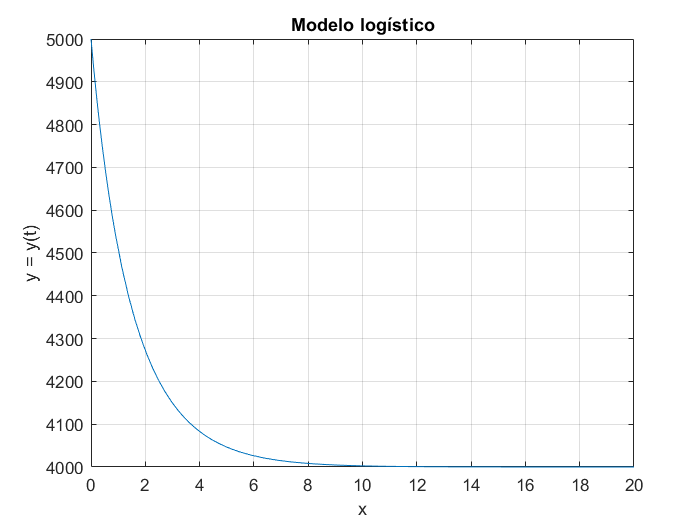


% Representación de la función y para t en [0, 20]. 
fplot(y2_2, [0, 20]), grid
xlabel('x'), ylabel('y = y(t)')
title('Modelo logístico')

### 1.3 - Diferencias en la evolución

Modelo logístico -> La capacidad de individuos crecerá hasta alcanzar la capacidad N (4000). Si inicialmente se tiene más individuos (1,2), la población irá disminuyendo hasta la posición de equilibrio, es decir, hasta alcanzar el valor de capacidad.